# Matched Filtering

In this script, we take a different approach to radar signal processing. In the preceding labs, we emitted a linear frequency modulated signal and mixed the transmit signal with the receive signal in the analog domain to generate a beat frequency corresponding to the range of targets in the field of view of the radar.

In this lab we demonstrate another common type of radar signal processing approach called matched filtering. In matched filtering, we transmit a signal once again occupying the bandwidth of interest, and correlate the known signal with the measured reflections. Matched filtering can be used to increase range resolution with in a fixed transmit time or to increase signal to noise ratio with a fixed signal bandwidth.

## Waveform Setup and Simulation Demonstration

clear;
close all;
warning('off','MATLAB:system:ObsoleteSystemObjectMixin');

For this lab, we use a phase coded waveform to demonstrate the matched filtering concept. Phase coded waveforms maintain a fixed signal amplitude while varying the signal phase at discrete intervals called 'chips'. Phase coded waveforms are commonly used in radar because of they work well as matched filters. In this case we use a Frank Code, which is just a specific way to define a phase coded waveform.

We first setup a waveform that is compatible with the phaser board. The sample rate for the board is limited to ~30 MHz.

% Setup system and waveform parameters
fc = 10.2e9;
prf = 10000;
fs = 30e6;
tpri = 1/prf;
duty = 0.5;
tpulse = tpri*duty;
nchips = 625;
tchip = tpulse/nchips;
sampleperchip = round(tchip*fs);
tchip = sampleperchip/fs;

% Create PCW using Frank codes
wav = phased.PhaseCodedWaveform(Code="Frank",SampleRate=fs,PRF=prf,...
    NumChips=nchips,ChipWidth=tchip);

% Create matched filter and get waveform samples
waveform = wav();

We plot the waveform magnitude and phase below. We can see that the magnitude is fixed but the phase varies as discrete intervals. Zoom in to see the individual chips, which are times of fixed phase.

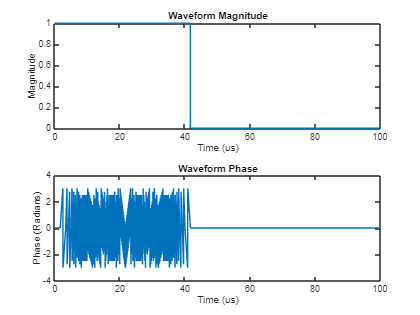

helperPlotWaveform(waveform,fs);

We then simulate a simple scenario to illustrate the usefulness of matched filtering. Consider a situation where we have two targets, one at 50 m and one at 70 m. Ignoring any amplitude reduction for the further target, we can represent the time delay of our waveform by shifting it the appropriate number of samples.

% Set target ranges
ranget1 = 50;
ranget2 = 70;

% Get number of samples to delay our waveform for each target.
timet1 = range2time(ranget1);
sampledelayt1 = round(fs*timet1);
timet2 = range2time(ranget2);
sampledelayt2 = round(fs*timet2);

% Our received signal is made up of two copies of our transmitted signal
% with appropriate delays
rxsignal = circshift(waveform,sampledelayt1) + circshift(waveform,sampledelayt2);

If we simply plot the magnitude of the received signal, it is impossible for us to distinguish between the two target returns.

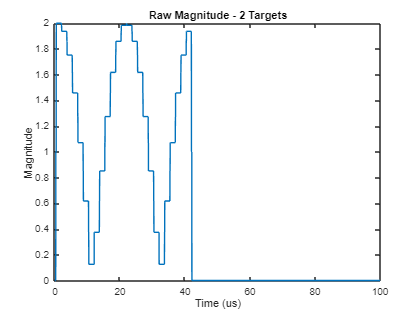

plotMagnitude(rxsignal,fs,'Raw Magnitude - 2 Targets');

However, by applying a matched filter, we can clearly distinguish between the returns of the two targets. Zoom in on the plot below to see the two target peaks after matched filtering.

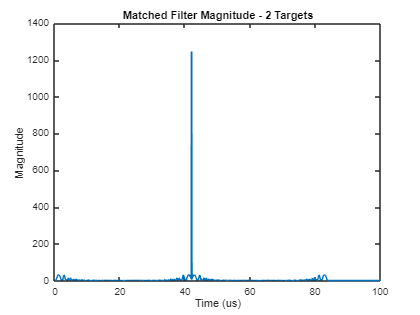

mfcoeff = getMatchedFilter(wav);
mf = phased.MatchedFilter(Coefficients=mfcoeff);
mfout = mf(rxsignal);
plotMagnitude(mfout,fs,'Matched Filter Magnitude - 2 Targets')

## System Setup

We now setup the system. In this case, instead of sweeping the oscillator to generate an FMCW chirp, we set the oscillator to a fixed carrier frequency and modulate the carrier frequency using the waveform created in the previous section.

[rx,tx,bf,bf_TDD] = setupLabRadarFixedLO(fc,fs,prf);

## Data Collection

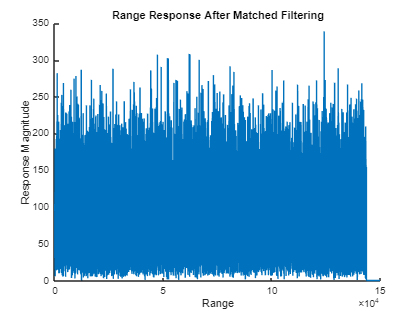

% Run time in seconds
tCapture = 30;

% Create a range response for processing using matched filter
rr = phased.RangeResponse(RangeMethod="Matched filter",SampleRate=fs);

% Create axes to plot range response
ax = axes(figure);
hold(ax,"on");
respline = plot(ax,0,0);
title(ax,"Range Response After Matched Filtering");
xlabel(ax,"Range");
ylabel(ax,"Response Magnitude");

% Capture the first waveform which typically has 0 values
captureTransmitWaveform(rx,tx,bf,waveform);

t = tic;
while toc(t) < tCapture
    % capture data
    data = captureTransmitWaveform(rx,tx,bf,waveform);

    % Sum data channels using digital calibration weights
    data = applyDigitalCalWeights(data);

    % Calculate the range-Response using matched filtering
    [resp,range] = rr(data,mfcoeff);

    % Plot the mf response
    set(respline,'XData',range,'YData',abs(resp));

    drawnow;
end


% Cleanup Phase
cleanupAntenna(rx,tx,bf,bf_TDD);

## Helper Functions

function helperPlotWaveform(wf,fs)
    % Setup figures
    f = figure;
    tl = tiledlayout(f,2,1);
    magax = nexttile(tl);
    phaseax = nexttile(tl);

    % Plot magnitude
    plotMagnitude(wf,fs,'Waveform Magnitude',magax);

    % Plot angle
    plotPhase(wf,fs,'Waveform Phase',phaseax);
end

function plotMagnitude(wf,fs,tstr,ax)
    arguments
        wf
        fs
        tstr
        ax = axes(figure)
    end

    n = length(wf);
    dt = 1/fs;
    t = 0:dt:dt*(n-1);
    tus = t*1e6;
    plot(ax,tus,abs(wf));
    title(ax,tstr);
    ylabel(ax,'Magnitude');
    xlabel(ax,'Time (us)');
end

function plotPhase(wf,fs,tstr,ax)
    arguments
        wf
        fs
        tstr
        ax = axes(figure)
    end

    n = length(wf);
    dt = 1/fs;
    t = 0:dt:dt*(n-1);
    tus = t*1e6;
    plot(ax,tus,angle(wf));
    title(ax,tstr);
    ylabel(ax,'Phase (Radians)');
    xlabel(ax,'Time (us)');
end